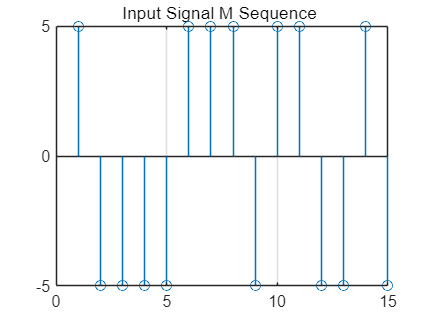

      
% Identification using the weighted least squares method

clear all;

randn('seed', 100);
v=randn(1,16);         % Generate a set of random noise with a Gaussian distribution of 16 N (0,1)
lambda=0.95;

% M-sequence generation program
L=15;                   % The period of the M sequence
y1=1; y2=1; y3=1; y4=0; % Output initial values of four shift accumulators
for i=1:L;
    x1=xor(y3, y4);
    x2=y1;x3=y2;x4=y3;
    y(i)=y4;
    if y(i)>0.5, u(i)=-5;
        else u(i)=5;
    end
    y1=x1; y2=x2; y3=x3; y4=x4;
end

figure(1)
stem(u), grid on;
title('Input Signal M Sequence ');

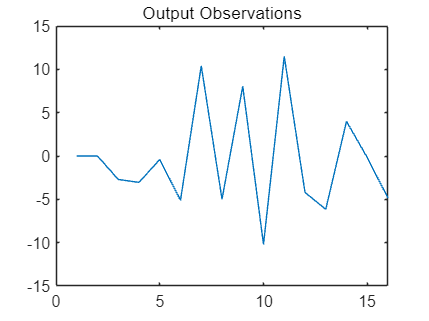



% Obtain the input-output data
y=zeros(1,16); % Define the length of output observations
for k=3:16
    y(k)=-1.5*y(k-1)-0.7*y(k-2)+u(k-1)+0.5*u(k-2)+1*v(k);% Observations
end

figure(2)
plot([1:16], y)
title('Output Observations');

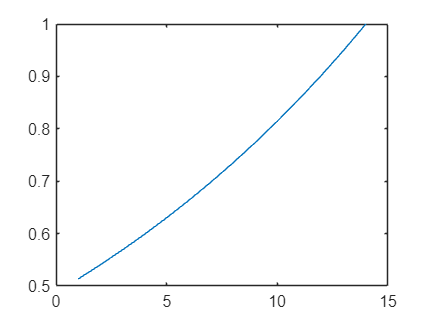



% The weighting matrix
for k=3:16 beta(k-2)=lambda^(16-k); end
plot(beta)

Beta=diag(beta);
BetaI = eye(16-2);

% Provide sample coefficient matrix
H= [-y(2) -y(1) u(2) u(1); 
    -y(3) -y(2) u(3) u(2); 
    -y(4) -y(3) u(4) u(3); 
    -y(5) -y(4) u(5) u(4); 
    -y(6) -y(5) u(6) u(5); 
    -y(7) -y(6) u(7) u(6); 
    -y(8) -y(7) u(8) u(7); 
    -y(9) -y(8) u(9) u(8); 
    -y(10) -y(9) u(10) u(9); 
    -y(11) -y(10) u(11) u(10); 
    -y(12) -y(11) u(12) u(11); 
    -y(13) -y(12) u(13) u(12); 
    -y(14) -y(13) u(14) u(13); 
    -y(15) -y(14) u(15) u(14)];

% Provide sample observation matrix
Z=[y(3);y(4);y(5);y(6);y(7);y(8);y(9);
   y(10);y(11);y(12);y(13);y(14);y(15);y(16)];

% Calculate parameters
c=inv((Beta*H)'*H)*(Beta*H)'*Z

c =     1.4964
    0.6985
    0.9661
    0.4845


inv(H'*BetaI*H)*H'*BetaI*Z

ans =     1.4959
    0.6969
    0.9662
    0.4816


% Separation parameters
a1=c(1), a2=c(2), b1=c(3), b2=c(4)

a1 = 1.4964

a2 = 0.6985

b1 = 0.9661

b2 = 0.4845